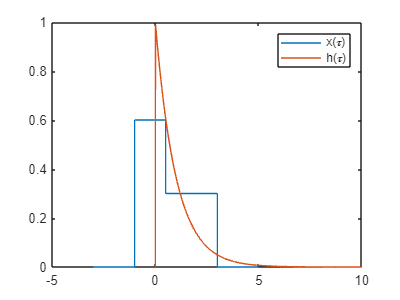

th1 = 0:0.01:10;
th = [0 th1];
h1 = exp(-th1).*heaviside(th1);
h = [0 h1];

tx1 = -1:0.01:0.5;
tx2 = 0.5:0.01:3;
tx3 = 3:0.01:5;
tx4 = -3:0.01:-1;
x1 = ones(size(tx1)) * 0.6;
x2 = ones(size(tx2)) * 0.3;
x3 = zeros(size(tx3));
x4 = zeros(size(tx4));
x = [x4 x1 x2 x3];
tx = [tx4 tx1 tx2 tx3];
figure 
plot(tx, x, th, h)
legend("x(\tau)", "h(\tau)")

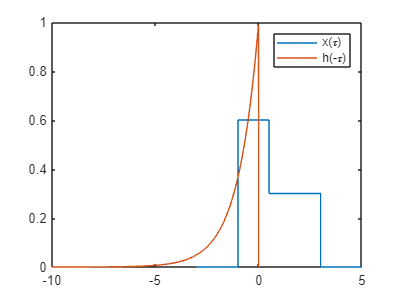


figure
plot(tx, x, -th, h)
legend("x(\tau)", "h(-\tau)")

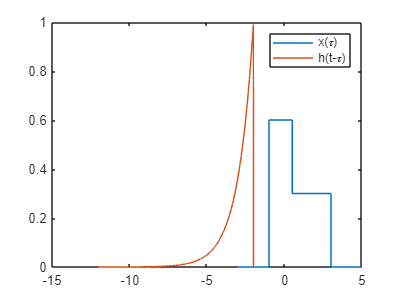


%Primeiro estagio
t = -2;
figure
plot(tx, x, t-th, h)
legend("x(\tau)", "h(t-\tau)")

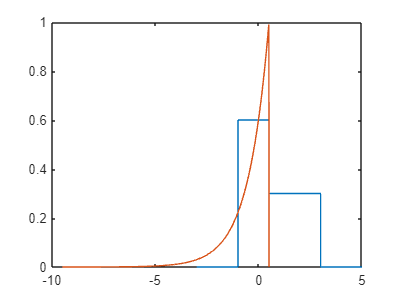


%Segundo estagio 
t = 0.5;
figure
plot(tx, x, t-th, h)

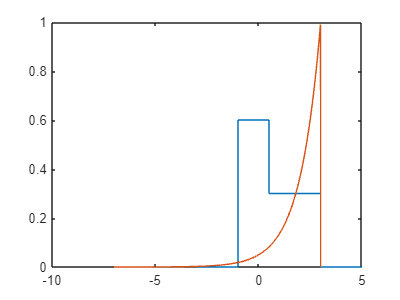


%Terceiro estagio 
t = 3;
figure
plot(tx, x, t - th, h)

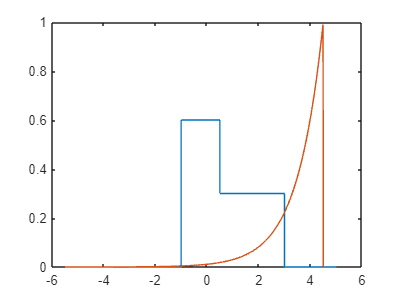


%Quarto estagio 
t = 4.5;
figure
plot(tx, x, t - th, h)

syms t r
f = 0.18*exp(t-r);
int(f, r, 0, t)

$$ans = \frac{9\,{\mathrm{e}}^{t}}{50}-\frac{9}{50}$$

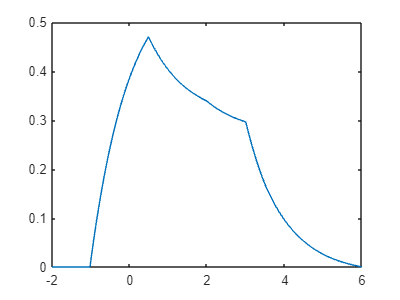

%comando conv
%intervalo é de -1 a 3
step = 0.01;
t1 = -1:step:0.5;
t2 = 0.5:step:3;
x1 = ones(size(t1)) * 0.6;
x2 = ones(size(t2)) * 0.3;
x = [x1, x2];
th2 = 0:step:3;
th1 = -1:step:0;
h1 = zeros(size(th1));
h2 = exp(-th2);
h = [h1 h2];
y = conv(x, h) * step;
ty = -2:step:6;
y(:, [1, 2]) = [];
plot(ty, y)

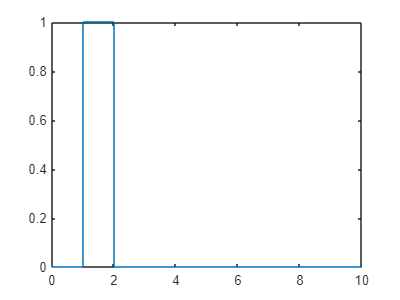

%Exercicio 02
t1 = 0:0.01:1;
t2 = 1:0.01:2;
t3 = 2:0.01:10;
t = [t1 t2 t3];
x1 = zeros(size(t1));
x2 = ones(size(t2));
x3 = zeros(size(t3));
x = [x1 x2 x3];
h = x;
plot(t, x)

figure
plot(t, h)

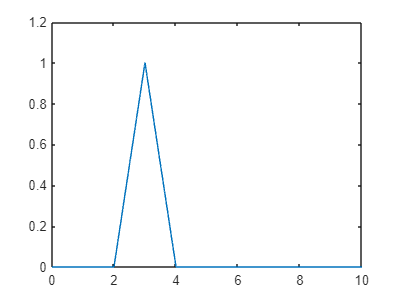

step = 0.001;
t = 1:step:2;
x = ones(size(t));
h = ones(size(t));
ys2 = conv(x, h) * step;
t1 = 0:step:2;
t2 = 2:step:4;
t3 = 4:step:10;
ys = [zeros(size(t1)) ys2 zeros(size(t3))];
ts2 = [t1 t2 t3];
plot(ts2, ys)

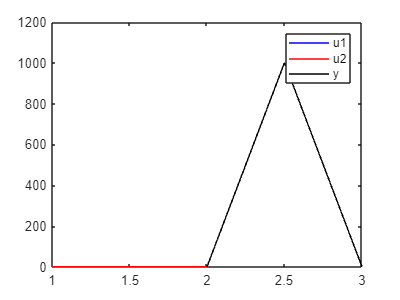

t = linspace(1,2,1001); % vetor de tempo de 1 a 2, com 101 pontos
u1 = ones(size(t)); % sinal degrau unitário 1
u1(t<1) = 0; % torna o sinal 0 antes de t=1.5
u2 = ones(size(t)); % sinal degrau unitário 2
u2(t<1) = 0; % torna o sinal 0 antes de t=1.8
ys2 = conv(u1,u2); % convolução dos sinais
ty = linspace(2,3,2001); % vetor de tempo para o sinal resultante
plot(t,u1,'b',t,u2,'r',ty,ys2,'k') % plota os sinais
legend('u1','u2','y') % adiciona legenda